# Exercise 1

## Using a Kalman Filter for a Holonomic Robot

### About This Exercise

Thus far we have assumed complete certainty about both the movements of the robot and the accuracy and precision of our sensors. However, life is not perfect and errors abound. In this course we will introduce the inevitable uncertainty inherent to robotics and one of the most common ways to handle uncertainty: the Kalman Filter.

You will use the Kalman Filter to solve the localization problem. In the previous exercises, you have  had access to some overhead sensor that provided the pose of the robot in the global frame directly. However, the range sensors and beacon sensors can provide information on where the robot is with respect to them, and you can combine those data streams to estimate the location of the robot. Given the assumptions discussed in the videos (such as the linearity of the system and the Gaussian nature of the noise), the Kalman Filter provides the best prediction of where the robot is given the sensor data and the previous movement.

In this exercise you will focus on how acquiring new sensory data improves the estimate of a holonomic robot over simple dead reckoning. We will then add different sensors and adapt the Kalman filter to work with the non-linear, non-holonomic, differential drive robot. 

**By the end of this exercise, you'll be able to: **

- **Localize a robot using a generic Kalman filter that will work for any linear system that has process and measurement noise.**

*Remember to connect with your peers and the course facilitator if you get stuck or need help working through any part of this exercise.*

### Dead Reckoning and Process Noise

The 'process' is what takes the system from one state to the next given the current controls, which we represent using the kinematic equations. If the robot was perfect and the starting state was known, you could simply update the position each time step according to the kinematics, which we call dead reckoning. However, the robot is not perfect, so we introduce noise to the process which tells you how accurate movements are given the same control. Process noise is similar to the spread of locations on the dartboard you might hit throwing over an over, all while trying to do the same exact motion every time with the same dart. The higher the spread, the less you can trust your nerves, muscles, and perhaps even the environment the dart flies through.

First, we'll simulate a trajectory with process noise to show how this uncertainty affects the movement of the robot.

- Load map

map = load('MAP102.txt');

- Define robot starting location (just x,y) and the time step

robotXY = [-1.5; -.5];
dt = 0.05;

- First start with control input (u = [Vx;Vy]) Travel east with speed of 1 m/s for 2 seconds, then travel west with a speed of 0.5 m/s for 2 seconds. 

**Complete the code below.**

N = round(2/dt); % Number of timesteps for two seconds
Vx = [ones(1,N), -0.5*ones(1,N)]; % 1 velocity for first second, -0.5 velocity for next second (row vector length N)
Vy = [zeros(1,N), zeros(1,N)]; % 0 velocity for first second, 0 velocity for next second (row vector length N)
u = [Vx; Vy];  % Concatenate into a single 2 x N control matrix

- Matrix A and B define the kinematic equations for a holonomic robot $x_{t+1} = Ax_t + B u_t$. Recall that the holonomic equation for $x$ is $x_{t+1} = x_t + u_x dt$ and similar for $y$. What then should $A$ and $B$ be?

**Complete the code below.**

A = [1 0; 0 1]; % 2 x 2 matrix
B = [dt 0; 0 dt]; % 2 x 2 matrix

- The Matrix R is the covariance matrix for the process noise, the higher the variance the less accurate dead reckoning will be.

variance = .14; %Change value here
R = [variance 0; 0 variance];

- Here we generate a noisy robot trajectory by looping through the control inputs u and applying the kinematic updates for each time step. The robotXYtraj is the predicted path using dead reckoning, while the robotXYtrajNoisy is the 'true' path the robot takes.

robotXYtraj = zeros(2,1+length(u)); % Allocate
robotXYtrajNoisy = zeros(2,1+length(u));
robotXYtraj(:,1) = robotXY; % Initialize
robotXYtrajNoisy(:,1) = robotXY;
for i = 1:length(u)
    robotXYtraj(:,i+1) = A*robotXYtraj(:,i) + B*u(:,i); % Kinematics without noise
    robotXYtrajNoisy(:,i+1) = A*robotXYtrajNoisy(:,i) + B*u(:,i) +  ...
                              dt.*sqrt(R)*randn(2,1); % Kinematics with noise
end

- Plot the resulting noisy trajectory versus the non-noisy one. Adjust the slider above to see the effect of the process noise.

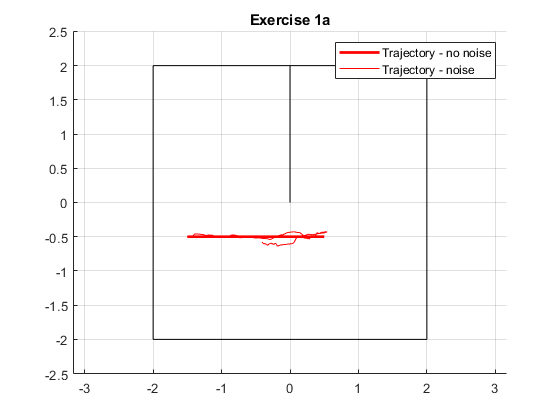

plot_title = "Exercise 1a";
external_figure = 1; % you can choose "1" to have an external figure or "0" to turn this feature off.
plotTraj(map, robotXYtraj, robotXYtrajNoisy, plot_title, external_figure); 

What do you notice about the trajectory as you change the variance?

### Noisy Measurements

Let's simulate some noisy measurements (as we do not have a physical sensor to give us noisy measurements) and simply plot the data so that you can gain some intuition about how the noise is structured. To do this we will use a function called ExpectedMeasurementLidar that gives the expected measurements of 4 range sensors. Beacuse the robot's orientation is constantly facing east, the 4 range sensors will always face west, north, east, and south directions (given by the vector alpha below). This exercise is for a linear holonomic robot where the orientation always stays the same. 

We will use ExpectedMeasurementLidar often. It returns a vector of range measurements given a robot pose (or x,y positions assuming theta = 0), sensor angles, the map, and the maximum range of the sensor. It defaults to have the sensor located on the front of the robot with radius 0.13 m, but an optional fifth argument allows you to set the robot radius where the sensor will sit.

maxRange = 4;
alpha = [pi, pi/2, 0, -pi/2];
variance = .14; %Change Value Here

Create a covariance matrix populating the diagonal elements with the variance above.

Q = diag(repmat(variance,1,length(alpha)));

Loop throuth the 'true' robot trajectory and get the expected measurement as well as the 'true' noisy measurement for each timestep.

measurements = zeros(length(Q),length(robotXYtraj));
measurementsNoisy = zeros(length(Q),length(robotXYtraj));
for i = 1:length(robotXYtrajNoisy)
    measurements(:,i) = ExpectedMeasurementLidar(robotXYtrajNoisy(:,i),alpha,map,maxRange);
    measurementsNoisy(:,i) = measurements(:,i) + sqrt(Q)*randn(length(Q),1);
end

This plots the 'true' noisy measurements over the expected measurements, try different values for the variance. Where does the linearity assumption in the measurement model break?

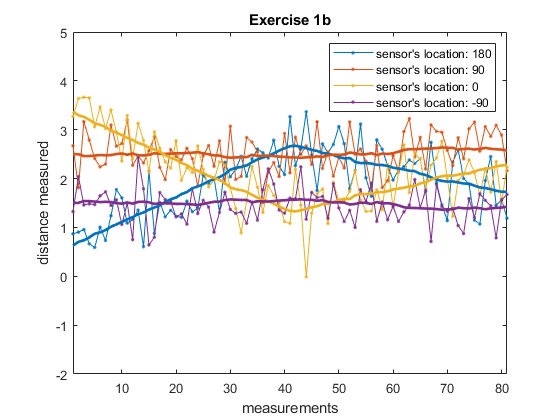

plot_title = "Exercise 1b"; 
external_figure = 1; % you can choose "1" to have an external figure or "0" to turn this feature off.
plot_measurements(measurementsNoisy, measurements, alpha,  plot_title, external_figure);

## The Kalman Filter

Now that you have seen both imperfect dead reckoning and noisy sensor data, how can you combine them into a best estimate of where the robot is? The answer we'll be exploring first is the Kalman filter.

The Kalman filter consists of two steps, the prediction step and the update step. The prediction step first calculates the state and uncertainty of the state given the equations of motion and the process noise, similar to the dead reckoning process above. The 'state' of a system is the set of variables needed to describe the system, and in this case is just the $x$ and $y$ coordinates of the robot position. As an input to the filter, we need an initial prediction of the state and the confidence in that prediction. We will explore the implications of that prediction. Given our predicted state, we then predict what measurements are expected for that state, using the ExpectedMeasurementLidar function described above.

In the update step, we calculate the difference between the predicted measurements and the actual noisy measurements from our sensors (which we simulated above). We then update our states and the uncertainty of those states based on that difference and the Kalman gain matrix. You can think of the Kalman gain as a factor between zero and one for each state, where the more reliable our sensors are relative to dead reckoning, the closer we get to 1. 

[► Complete the KF function](matlab:open('./KF.mlx')), which implements the Kalman filter given range sensor data.

## Run Kalman Filter in a Loop

The Kalman filter is iterative, meaning it is called for each instance in time where there are new control inputs and measurements. Here you will set up the inputs to the Kalman Filter and run it in a loop over the measurements we simulated above.

First, we define the true position of the robot (feel free to try different positions later).

robotXY = [-1.5; -.5];

Now you need to initialize the normal distribution (parameterized by $\mu$ and $\Sigma$) representing the initial guess of where the robot might be. The variable mu should be a 2x1 column vectorand sigma should be a 2x2 matrix. We'll start with a guess of $\mu$ = [-0.8; -0.8]. $\Sigma$ can be initialized to a diagonal matrix with relatively high values (like 2 meters).

**Complete the code below.**

mu_value = -.8; %Change value here
mu = [-.1; -.8];  % 2-by-1 vector
sigma_value = 2; %Change value here 
sigma = 2*eye(2);  % 2-by-2 matrix

Now you need to create the matrix C which relates the measurements to the robot state ($x,y$) according to the equation $z = Cx$ where $z$ is the column vector of measurements and $x$ is the column vector of the robot state. Thus the size of $C$ for this example is 4-by-2 as we have four measurements. In general, the equation above depends on the wall that the sensor is hitting. Create $C$ below, knowing that the sensor measurements are in the order west, north, east, south. 

**Complete the code below.**

C = zeros(length(alpha),2); %Create the C-Matrix
for i = 1:length(alpha)
    C(i,:) = [-cos(alpha(i)) -sin(alpha(i))]; 
end

Now we have the inputs, we can loop through the measurements and apply the Kalman Filter iteratively. Make sure all of the inputs are in the correct format. 

N = length(u);
mu_hist = zeros(2,N+1); 
sigma_hist = zeros(2,2,N+1);
mu_hist(:,1) = mu;
sigma_hist(:,:,1) = sigma;
for i = 1:N
    [mu,sigma] = KF(map, measurements(:,i+1), mu, sigma, A, B, C, R, Q, u(:,i), alpha, maxRange);
    mu_hist(:,i+1) = mu;
    sigma_hist(:,:,i+1) = sigma;
end

This function will create a figure where you can step through the updates to mu and sigma over time. The center of the ellipse is the current guess and the 2 axes of the ellipse indicate the uncertainty in the x and y locations. Given the covariance matrix Q, which axis of the ellipse should be longer? Is that true of the final ellipse (you may have to zoom in)? What happens to the ellipse from the initialized guess to the final estimate? How does this match your answers about increasing sampling size from the previous section?

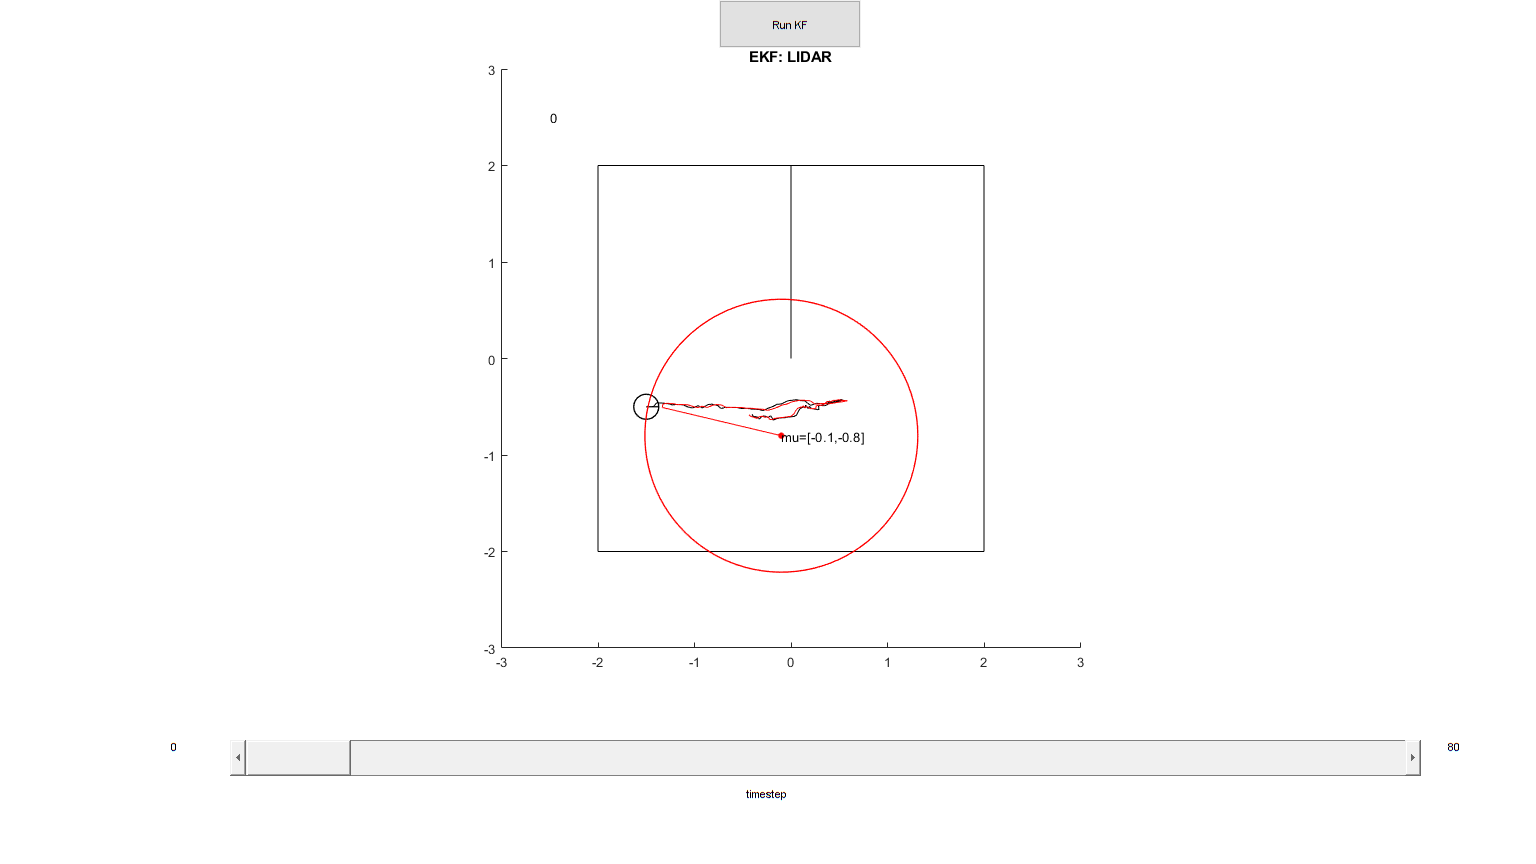

plotKF(mu_hist,sigma_hist,robotXYtrajNoisy,map, @LIDAR) 

The Kalman filter is based off of Bayesian inference, meaning that there has to be some prior knowledge to update the current belief of where the robot is given the data. The Kalman filter finds the optimal prediction based on that prior, which may sometimes give the wrong answer. Try different starting predictions (such as $\mu = [-0.8, 0.8]$ and report what other locations the Kalman filter might predict the robot to be given these measurements.

### Finished!

You now have coded a generic Kalman filter that will work for any linear system that has process and measurement noise. Most mobile robots cannot actually drive in both the x and y directions directly, and our differential drive robot is non-linear. In fact, most robots and processes in the world are non-linear. Luckily we can 'extend' the Kalman filter to non-linear systems. In the next assignment we will develop and apply the Extended Kalman Filter to our differential drive robot.